% convolution coding 
bit_stream = round(rand(10,1));
code = CCode(bit_stream,[ 1 0 0 1 1],[1 1 1 0 1]);


conv_poly = [23,35];  % g1 =[ 1 0 0 1 1] g2 = [1 1 1 0 1]
K = 5;
trel = poly2trellis(K,conv_poly);
tail = zeros(K-1,1);
isequal(code, convenc(bit_stream,trel))  % this is to test our convolution code

ans = logical
   1


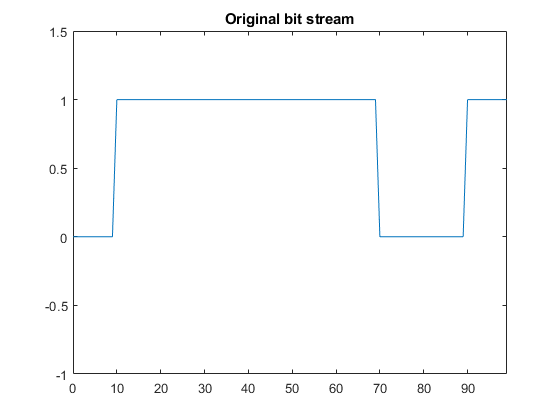



uu = bb_tx(bit_stream .',10,'RECT');
plot(0:99,uu.SJN)
axis([0 99 -1 1.5])    
title('Original bit stream')

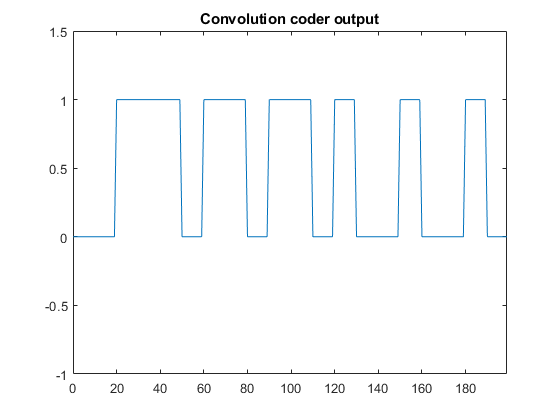


uu = bb_tx(convenc(bit_stream,trel) .',10,'RECT');
plot(0:199,uu.SJN)
axis([0 199 -1 1.5])    
title('Convolution coder output')           

% interleaving and deinterleaving illustration
bit_stream = round(rand(10,1));
interleaved = interleav(bit_stream, 2, 5);


isequal(interleaved, matintrlv(bit_stream ,2 ,5))   % this is to test our interleaving program

ans = logical
   1




deinterleaved = deinterleav(interleaved, 2, 5);     
isequal(bit_stream,deinterleaved)                               % this is to test our deinterleaving program

ans = logical
   1


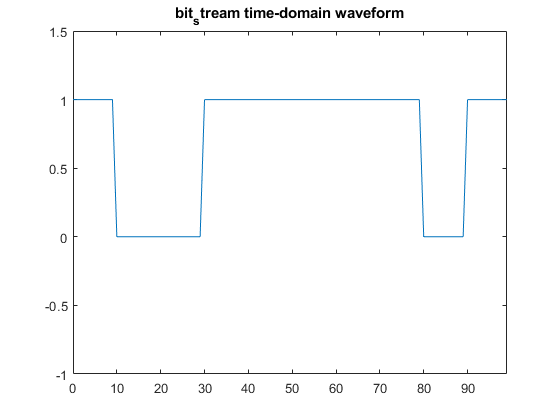










uu = bb_tx(bit_stream.',10,'RECT');
plot(0:99,uu.SJN)
axis([0 99 -1 1.5])                     
title('bit_stream time-domain waveform')

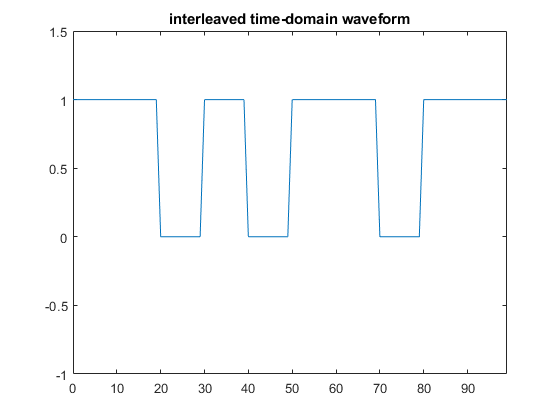


uu = bb_tx(interleaved .',10,'RECT');
plot(0:99,uu.SJN)
axis([0 99 -1 1.5])                    
title('interleaved time-domain waveform')

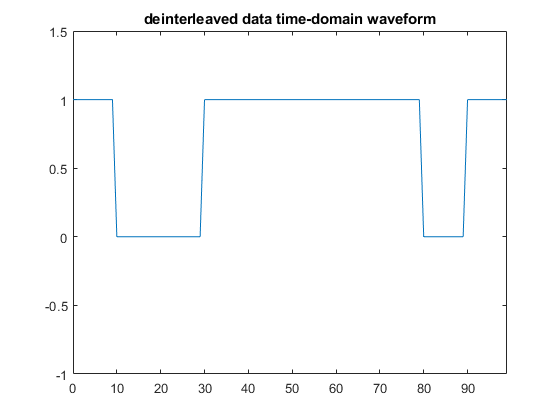


uu = bb_tx(deinterleaved  .',10,'RECT');
plot(0:99,uu.SJN)
axis([0 99 -1 1.5])                           
title('deinterleaved data time-domain waveform')

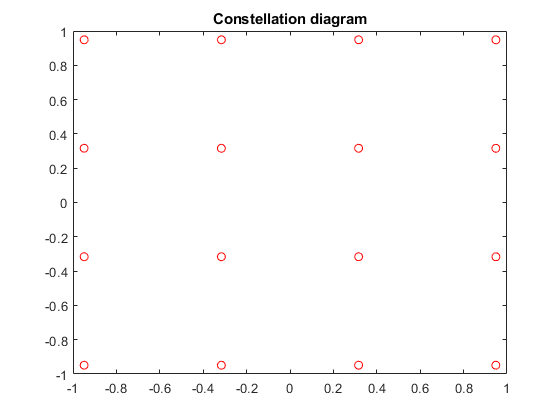

%16QAM modulation and demodulation
bit_stream = [ 0; 0; 0; 0; 
               0; 0; 0; 1;
               0; 0; 1; 0;
               0; 0; 1; 1;
               0; 1; 0; 0; 
               0; 1; 0; 1; 
               0; 1; 1; 0; 
               0; 1; 1; 1;
               1; 0; 0; 0; 
               1; 0; 0; 1; 
               1; 0; 1; 0;
               1; 0; 1; 1;
               1; 1; 0; 0; 
               1; 1; 0; 1;
               1; 1; 1; 0;
               1; 1; 1; 1];

y = qammod(bit_stream,2^4,'InputType','bit','UnitAveragePowe',true);
plot(real(y),imag(y),'ro');
title('Constellation diagram')




zz = qamdemod(y,2^4,'UnitAveragePower',true','OutputType','bit');
isequal(zz,bit_stream)

ans = logical
   1


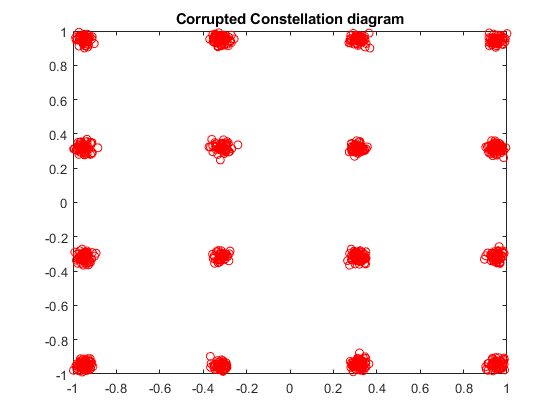






y = qammod(round(rand(2^12,1)),2^4,'InputType','bit','UnitAveragePowe',true);
y = y + 0.02*(randn(2^10,1)+j*randn(2^10,1));
plot(real(y),imag(y),'ro');
title('Corrupted Constellation diagram')
axis([-1 1 -1 1])

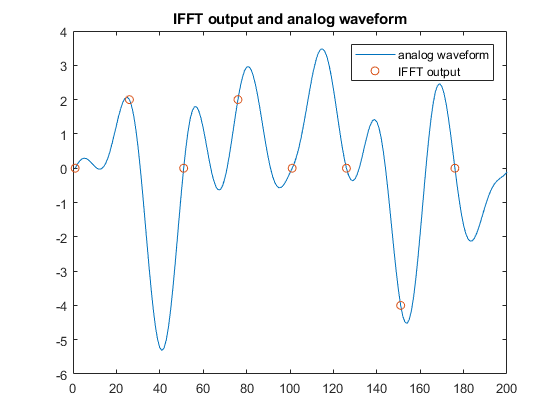

% Orthogonal Frequency-Division Multiplexing


B_subc = 15e3; %subcarrier
num_c = 4;     % 4 subcarrier

fc_0 = 15e3; % first carrier at 15KHz
fc_1 = 2*fc_0;
fc_2 = 3*fc_0;
fc_3 = 4*fc_0;


Ts = 1/fc_0;  %OFDM symbol duration
fs = 1500e3;  %analog sampling rate 


t = 0:1/fs:(2*Ts-1/fs); % countinuous time, two OFDM symbol
N = length(t)/2;      % number of samples per OFDM symbol

QAM_symbol = [1+1i 1-1i; -1-1i -1-1i; -1+1i 1-1i; 1-1i -1+1i];

sig_c0 = [QAM_symbol(1,1)*ones(1,N),QAM_symbol(1,2)*ones(1,N)].*exp(j*2*pi*fc_0*t);
sig_c1 = [QAM_symbol(2,1)*ones(1,N),QAM_symbol(2,2)*ones(1,N)].*exp(j*2*pi*fc_1*t);
sig_c2 = [QAM_symbol(3,1)*ones(1,N),QAM_symbol(3,2)*ones(1,N)].*exp(j*2*pi*fc_2*t);
sig_c3 = [QAM_symbol(4,1)*ones(1,N),QAM_symbol(4,2)*ones(1,N)].*exp(j*2*pi*fc_3*t);

s = sig_c0+sig_c1+sig_c2+sig_c3;

figure;
plot(real(s));    % this is to plot continuous waveform
tx = real(s);
hold on;
OFDM_symbol = 4*reshape(ifft([QAM_symbol(4,:); QAM_symbol(1:3,:)]),[8,1]);
plot(1:25:7*25+1,real(OFDM_symbol),'o');
legend('analog waveform','IFFT output');
title('IFFT output and analog waveform')

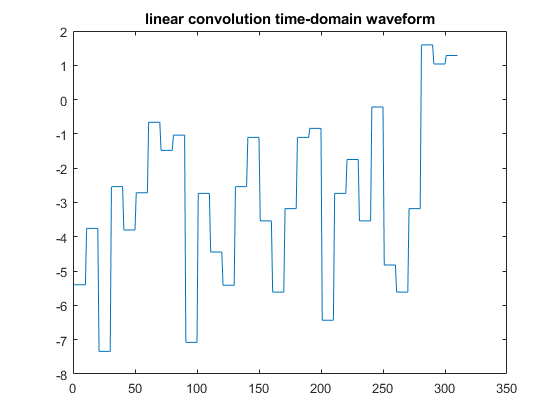



%------------------- this is to illustruate cp -------------------------
signal = [randi(3,1,10) randi(3,1,10)];
h = randn(1,4);
num_padding = length(h);

first_frame = signal(1:10);
second_frame = signal(11:end);

signal_pad = [signal(10 - length(h) +1 : 10 ) first_frame signal(20 - length(h) +1 : end) second_frame];


linear_filter = cconv(signal_pad,h);

circular_filter = cconv(first_frame,h,10);

figure
uu = bb_tx(linear_filter,10,'RECT');
plot(uu.SJN)                          
title('linear convolution time-domain waveform')

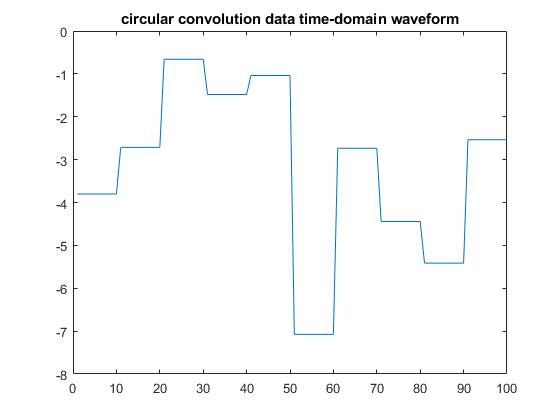


figure
uu = bb_tx(circular_filter,10,'RECT');
plot(uu.SJN)                          
title('circular convolution data time-domain waveform')